# VECM_demo.mlx

Joel Hasbrouck

November 7, 2018

- Simulate a small number of cointegrated prices

- Estimate a VECM of order P using Matlab's Econometrics Toolbox vecm routines.

- Construct a random-walk decomposition from the Matlab vecm estimates.

- Estimate the same VECM using the sparse routines in an MVARi object.

- Construct a random-walk decomposition from the MVARi estimates.

## Initializations and simulations

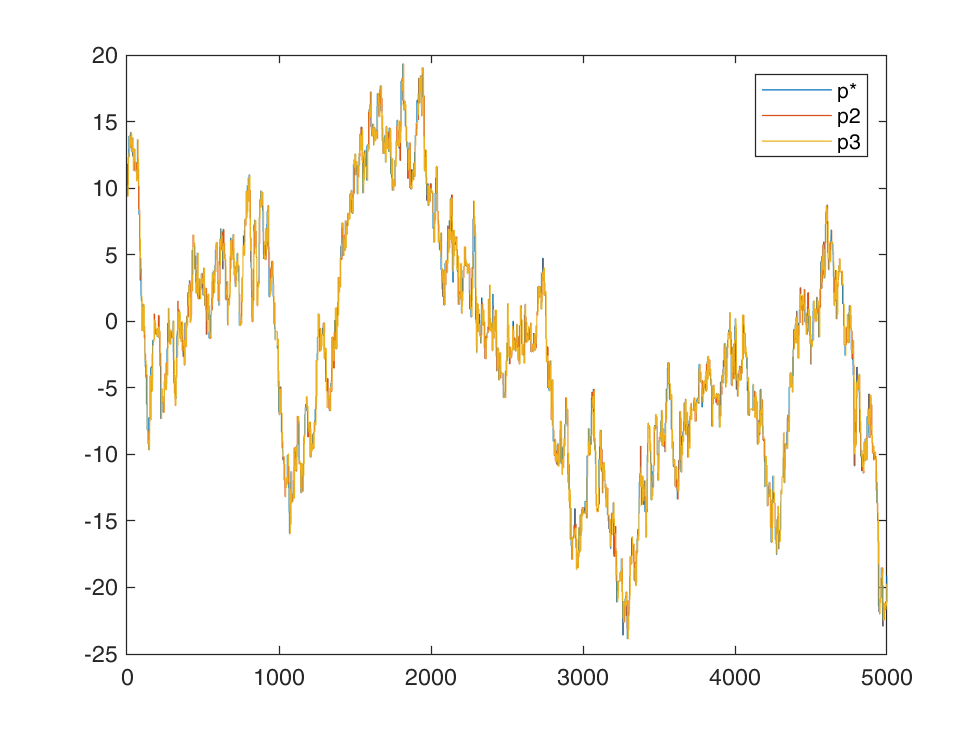

clc; clear all; close all
format compact
addpath('./mClasses','./mFiles')
rng('default')
mv = MVARi;
T=5000;
spd.setgetMax(T);
nPrices = 3;
density = .6;
mv.sim(density,nPrices,0,5) % The first price is the leader; other obs are randomly lagged between 0 and 3 intervals.
mv.pricePlot

## Estimation

Estimate with matlab VECM routines

P1 = 3; % order of AR
first = 100-P1; last=4900;  % defines window over which data will be analyzed.
xs = [];
for i=1:mv.nPrices
    xs=[xs mv.prices(i).toCol];
end
xs = xs(first:last,:);
xs = xs - repmat(mean(xs),size(xs,1),1);    % demean the data.
n = size(xs,2);
%   set up model
mdl = vecm(n,mv.nPrices-1,P1);
B = [ones(n-1,1) -eye(n-1)];
mdl.Cointegration = B';
mdl.Constant = zeros(n,1);
mdl.Trend = zeros(n,1);
mdl.SeriesNames = mv.priceNames;
[est,se] = estimate(mdl,xs,'Display','full','Model','H2','MaxIterations',1);

 
   3-Dimensional Rank = 2 VEC(3) Model
 
    Johansen Model: H2
    Effective Sample Size: 4800
    Number of Estimated Parameters: 33
    LogLikelihood: -12144.5
    AIC: 24355
    BIC: 24568.8
 
                           Value       StandardError    TStatistic      PValue   
                        ___________    _____________    __________    ___________
    Adjustment(1,1)     -0.00065459       0.02114       -0.030964          0.9753
    Adjustment(2,1)         0.58275      0.016206          35.959     3.5983e-283
    Adjustment(3,1)        -0.03999      0.016313         -2.4513        0.014232
    Adjustment(1,2)        0.010767      0.021329         0.50479         0.61371
    Adjustment(2,2)      -0.0033231      0.016351        -0.20324      

% [est,se] = estimate(mdl,xs,'Display','full','MaxIterations',1);

Now perform the same estimation using the sparse routines.

The sparse routines are set up using polynomial distributed lag specifications. Here, we want the usual AR terms. This is done by setting the polynomials to that the the design matrix is the identity matrix of order P1.

pdls = polynom.empty();
for k=1:P1
    pdls = horzcat(pdls,polynom(0,1,['pdl' int2str(k)],k-1));
end

The design matrix works out to the identity matrix:

pdls.designMatrix

ans =      1     0     0
     0     1     0
     0     0     1


Now finish the estimates.

mv.polys = pdls.copy();
mv.intercept = false;
mv.ecm = true;
mv.setup(true);

setup.
Computing eVecs


mv.setNamesPDL(true);

zNames:
const              dp*                dp*pdl1d0          dp*pdl2d0          dp*pdl3d0          dp2                
dp2pdl1d0          dp2pdl2d0          dp2pdl3d0          dp3                dp3pdl1d0          dp3pdl2d0          
dp3pdl3d0          p*-p2              p*-p3              
yNames:
dp*                dp2                dp3                
xNames:
dp*pdl1d0          dp*pdl2d0          dp*pdl3d0          dp2pdl1d0          dp2pdl2d0          dp2pdl3d0          
dp3pdl1d0          dp3pdl2d0          dp3pdl3d0          p*-p2              p*-p3              


mv.zpzLayoutPDL();
mv.firstValid = first; mv.lastValid = last;
mv.eVecDemean(true);

eVecMeans: -0.013494  -0.0010435


zpzDisplay = 1;
mv.buildzpzSparsePDLpar(zpzDisplay,0);

buildzpzSparsePDLpar (nCPU=0)
Across the full for/parfor loop, the start to finish elapsed time is 6.65 sec.


mv.estimateSparse();
mv.dispEstimates

VAR/VECM estimates
                  dp*         t        dp2         t         dp3         t
dp*pdl1d0    0.002285   0.09054    -0.3635    -18.78     -0.3111    -15.98
dp*pdl2d0    -0.01561   -0.6824    -0.2285    -13.04     -0.1462    -8.286
dp*pdl3d0    0.002222    0.1111   -0.08386    -5.468  -0.0004644  -0.03009
dp2pdl1d0    0.008581    0.4249    0.08927     5.767     0.02143     1.376
dp2pdl2d0    0.007757    0.4289  -0.001066  -0.07685     0.02893     2.074
dp2pdl3d0    0.006293    0.3811   0.005879    0.4644   -0.000984  -0.07725
dp3pdl1d0    -0.01164   -0.5717    0.01901     1.217     0.04103     2.612
dp3pdl2d0     0.01447    0.7957    0.02326     1.669     0.01911     1.363
dp3pdl3d0     0.01333    0.8144    0.01017      0.81   -0.007665   -0.6069
p*-p2      -0.0004345  -0.02055     0.5824     35.92    -0.04111    -2.521
p*-p3         0.01101    0.5161   -0.00276   -0.1687      0.5562     33.79
eCov
         dp*       dp2       dp3
dp*   0.4526   0.03289   0.03833
dp2  0.032

The two sets of estimates are quite close, but not identical to numerical precision. I have not determined the source of the discrepancies.

## Random-walk decompositions

The random-walk decomposition for the Toolbox vecm:

r = randomWalkDecomp;
r.initm(est);
r.isBoundsGrouped({{'p*'},{'p2','p3'}});
r.rDisplay('rwd from the toolbox vecm');

rwd from the toolbox vecm
Sum of vma coefficients:
     p*          p2        p3
  1.056  -0.0002178  -0.02046
per period var_w:    0.502749 sd_w:    0.709048
info share bounds:
        Min      Max
p*  0.98227  0.99978
p2  0.00000  0.00899
p3  0.00022  0.00907
Grouped info share bounds
           Min      Max
p*     0.98227  0.99978
p2 p3  0.00022  0.01773


The random-walk decomposition for the sparse (MVARi) vecm

r=randomWalkDecomp;
r.init(mv);
r.isBoundsGrouped({{'p*'},{'p2','p3'}});
r.rDisplay('rwd from the sparse vecm');

rwd from the sparse vecm
Sum of vma coefficients:
     p*          p2        p3
  1.059  -0.0006903  -0.02097
per period var_w:    0.505747 sd_w:    0.711159
info share bounds:
        Min      Max
p*  0.98249  0.99977
p2  0.00000  0.00887
p3  0.00023  0.00896
Grouped info share bounds
           Min      Max
p*     0.98249  0.99977
p2 p3  0.00023  0.01751


## IRF Computation (MVARi only)

nAhead = 20;
mv.irfPDLpacked(nAhead, 1, 0);

irfPDLpacked (nCPU=0)


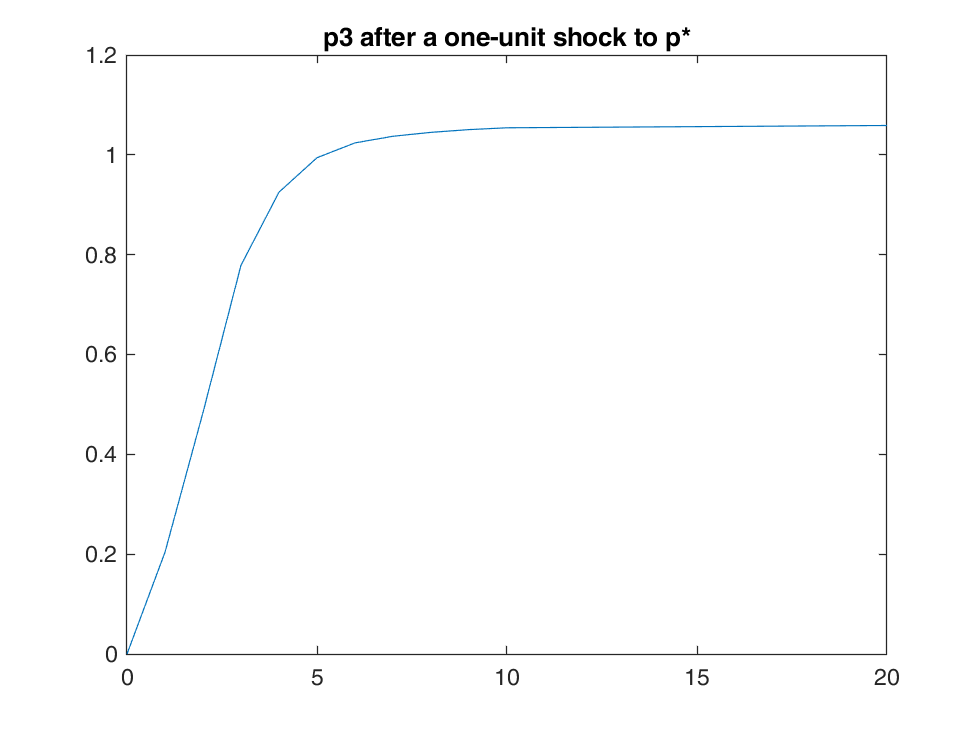

irf=squeeze(mv.irfPacked(3,:,1));
irft=mv.irft;
plot(irft,irf)
title('p3 after a one-unit shock to p*')